**Exploring_ODE**

Let me introduce a little bit simpe matlab tool as "Chebfun" especially in the ordinary differential equation. The refernce textbook is "Exploring ODE" in chebfun org(search in googling). 

Dynamic system means it change with respect to time in general, such that it may represents by 'Differential Equations' in mathmatical terminorlogy. 

**1. Introduction **

Consider a non-linear second order differential equation


$$0.3y" -(1-y^2)y' + y = 0, t\in [0, \ 20]$$


with initial conditions as 


$$y(0), y'(0) =1$$


following the previous tutotial, the code may be

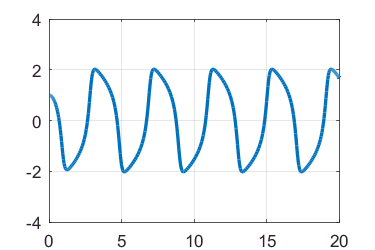

clear all;clf
LW ='linewidth';
figure('Renderer', 'painters', 'Position', [10 10 300 200])
N = chebop(0,20);
N.op = @(t,y) 0.3*diff(y,2) - (1-y^2)*diff(y) + y;
N.lbc =[1;0];
y = N\0;
plot(y, LW,2); grid on

Good. I would like to verify the solution( in fact, it is an approximated solution numerically in the matlan environment). let us plot a graph substituting the solution into the given equation 

source =0;
numSol = 0.3*diff(y,2) - (1-y^2)*diff(y) + y;
figure('Renderer', 'painters', 'Position', [10 10 300 200])
plot(numSol -source); grid on

I may zoom up the y scale as

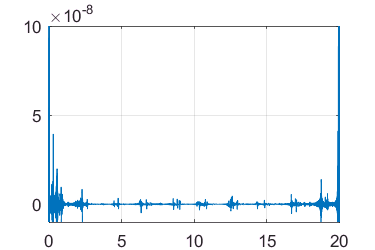

axis([0 20 -10^-8 10^-7])

[mval,mpos] =max(numSol - source)

mval = 2.2445e-05

mpos = 20

Then, the error between the numerical solution and the real solution(**which is not known analytically**) is small so that the maximum error is around $O(10^{-5})$at the right boundary! So, the numerical solution is "A" approximated solution. Is this the only numerical solution? **NO**. you may use "ode23, ode45,.." in matlab without help of "chebfun".But, in my opinion, use "chebfun", since

It is simple

It gives more flexibility

And it is new, there will be more apprications... Plz use it.

**2. Classification for ODEs**

In the mathematical dynamic models, it is good to classify  whether the methos to get solutions are different. 

 1) first order linear ODEs

 2) first order non-linear ODEs

 3) second order linear ODEs

 4) second order nonlinear ODEs

And so on. each ODEs are also subgrouped into autonomous and non-autonomous systems. Autonomous...in my point, it is not understandable easily.It may be changed into "time-invariant", and non-autonomous into "time- varying". It is better to unserstand.

**2.1 first order linear ODEs**

Consider a first order linear ODE


$$y' - a(t) y = g(t),  t\in [0 \ d]$$


Here  if $a(t)$ is constant , we may call autonomous (time -invariant) otherwise non-autonomous (time varying) ODE. Futher more, if $g(t)  = 0$, then "homogeneous" ODE otherwise, non-homogeneous ODE. There are many examples in the text book as

 
$$y' - ay=0, y(0) = y_0 $$



$$y'- sign(sin(t^2))y = 0, $$



$$y' - sin(t^2)y = 0$$



$$y' + y = sin(t^2)$$



$$y' + y = e^{3t}$$



$$y' + ty = t e^{t^2}$$


and so on. Even if ODE is a first order, there are many things to interest us.Now in text Application in real life, a little bit strange to electrical engineers. 

**Application_1: enjoy coffee**

A.1 Problem statement:

  To drink a cup of coffee, the body absorbs a dose of caffeine and take some time to clear it away. find a caffeine level in blood after drinking coffee.

A.2 A mathematical model

 Let define $c(t) $be the caffeine level in the blood. Assume $c(t) $ to satisfy the following ODE 


$$c'(t) = -kc(t) +f(t)$$


here, $k$is a positive rate constant and $f(t)$is the caffeine concentration rate due to drinking coffee.

A.3 Information to identify $k$and $f(t)$

-   $k$ half-life time $t_{1/2}$

    In order to determine (or estimate) the value of $k$, it is useful to use "half-life time" , i.e.,

    half-life time = the time required for a quantity to reduce to half of its inintial value.

    Consider 


$$c'(t) = -kc(t), c(0)=c_0 $$


    Then

  
$$c(t) = c_0 e^{-kt}$$


    which implies if you measure half-life time $t_{1/2}$

 
$$\frac{1}{2} = \frac{c(t_{1/2})}{c_0} =  e^{-kt_{1/2}  \\


t_{1/2} = log(2)/k$$


    We may assume $t_{1/2} = 6 hours$ then

clear all;clf
LW ='Linewidth';
t12 =6; k = log(2)/t12;

-   the caffeine concentration rate by drinking coffee

 Assume, the amount of caffeine in a large mug is 300mg, which creats a concentration of about $8 \mu g/mL$ in a half hour.Suppose  coffee is consumed at 7:00 , 10:00 and 15:00 so that in a day the intake schedule with time (unit is hour) is 

t  = chebfun(@(t)t, [-2, 24]);
coffee = @(t0) 16*(t>t0)*(t<t0 + 0.5);
intake = coffee(0) + coffee(3) + coffee(8);
figure('Renderer', 'painters', 'Position', [10 10 300 200])
plot(intake,LW,2); hold on; grid on
axis([-2 24 -5 20])

**Here  a chebfun and an anonymous function are used as "t" and "coffee" respectively.**

-  mathematical solution

 Let us define an " cheb operator"  and make a code 

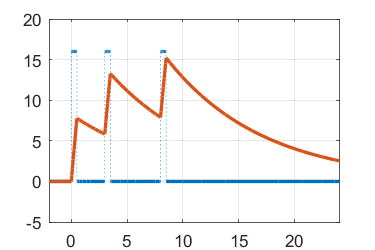

L = chebop(@(t,c) diff(c) + k*c,[-2, 24]);
L.lbc = 0; 
c = L\intake; hold on 
plot(c, LW,2)

-   discussion the results

  In the graph, the caffeine level is displed in a day. at the midnight(t=24), the concentraion level $c(t=24) = 2.62(\mu g/mL)$.Three cups of coffee is  too much to clear caffeine in your blood!  If we drink coffee in the same time interval regularly,

intake_reg = coffee(0) + coffee(8) + coffee(16);
c_reg = L\intake_reg; 
plot(c_reg, LW,2)

The concentration is higher but the maximum of it is lower. If you drink a cup of coffee 3 times larger , 48 $\mu g /mL$ but just one time in the mornig, 

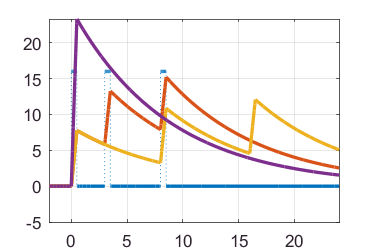

intake_one = 3*coffee(0);
c_one = L\ intake_one;
plot(c_one,LW,2)

Even if the amount of coffee in a day is the same, the concentration level is different. 

Let us consider the following case, 

1) the maximum of concentration is the intake_one 

2) At the 24 hour, the concentration is the highest in case of regular time interval

 3) The toal amount of the caffeine in the blood in a day is

[sum(c)  sum(c_reg) sum(c_one)]

ans =   185.7643  163.7745  194.3815


so that the smallest is the regular time drinking case. Which one is the best for your health? I do not know, the regular time interval, if the final concentration is allowable, is the best for your health,,, But I am not sure!

**Application_2: Temperature of a body(estimate the death time)**

Here is another interesting problem. see Exercise 2.8. 

**2.2 First-order scalar non-linear ODEs**

Non-linear ODE's are modeled as 


$$y' + h(y) = f(t)$$


here $h(y)$is not linear, for example


$$y' + y^3 = 3cos(t)$$


Here the term "y" is non-linear. In the non-linear ODEs, the basic question is,**The existance and uniqueness.** The exsitence and uniqueness of the solution is guaranted in the linear ODE, but in non-linear case, it depends on the $h(t)$, sometimes there is no solution and sometimes infinite many solutions.

1) no solution case

consider 

 
$$y' = y^2 , y(0) = 1$$


By inspection, or your heuristically intuition, a solution is


$$y = \frac{1}{1-t}$$


Hence at $t=1, y(t=1) = \infty $, which implies for any finite interval $t \in [0, t_b] ,  t_b > 1$, there is no solution. (you may think except $t=1$, it may be the solution, however it violates the interval condition). This is a physical situation as a thermal-run away case.think about a fire match)

 2) infinite many solutions

Consider 


$$y' = y^{1/2}, y(0) =0$$


By inspection, or your heuristically intuition, a solution is


$$y(t)= \frac{1}{4} t^2 $$


But another solution is 

                                              $y(t) = 0$.

Moreover  for any $t_0 \ge 0,$

  
$$y(t) = {
 \begin{cases} 
0,   \   \  \  \ t  \le t_0 \\
\frac{1}{4} (t-t_0)^2 , t \ge t_0 .
 \end{cases}  


$$


$y(t)$ is a solution, which implies there are infinite solutions to the  ODE.

Application_3 : classic pursuit problems

This is a old fashioned missile guidance to attack an airplane, so called pursuit evasion problem. The missile is steered always to the direction of the line of the sight  (https://en.wikipedia.org/wiki/Pursuit_guidance).

A.1 problem statement

 Suppose an antelope runs with a speed 1 along the vertical line x=1 starting at (1,0), going in the positive y-direction. A lioness starts at (0,0) and pursuit the antelope, always moving directly toward the antelope at a fixed speed $C$. What path does the lioness follow, and when and where does she catch the entelope?

A.2 information

The speed of the lioness is constant but, the direction is always to ward the antelope. 

A.3 mathmatical modeling

the movements of them are in 2D -(x,y) plane, however, we may consider the complex plane which is 2-D.

Hence the antelope and lioness path are given as


$$a(t) = 1 + it 
$$


here $i^2 = -1$ and $t$ is a time variable.

Then the lineness movement  $z(t) $is 


$$z'(t) =\frac{dz}{dt}= C\frac{a(t)-z(t)}{\ | a(t) - z(t)  \ |      $$


 Here the direction of the lioness is 


$$\frac{a(t)-z(t)}{\ | a(t) - z(t)  \ |$$


which is the absolute value is 1. 

The governing ODE is coded as

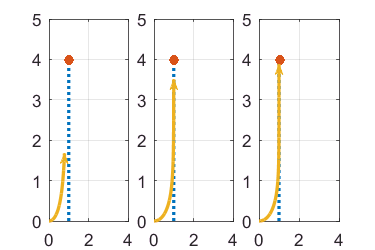

clear all;clf
LW = 'linewidth';
MS = 'markersize';
tmax = 4; 
a = chebfun(@(t) 1+1i*t, [0  tmax]);
N = chebop(0,tmax);
N.lbc = 0;
CC = [0.5 1 1.1];
for j = 1:3
    C=CC(j);
    N.op=@(t,z) diff(z) - C*(a(t) -z)/abs((a(t)-z));
    subplot(1,3,j),plot(a,':',LW,2); hold on; grid on
    axis([0 4 0 5])
    plot(a(end),'.',LW,2,MS,20);
    z = N\0;
    arrowplot(z,LW,2)
end

  A.4 Discussion

Here, if the lioness speed is 0.5, it will never catch the antelope, whereas it is greater then 1, it will catch the antelope.

Now if the antelope may zig-zag, such that it will turn to the right at $t =2, $then 

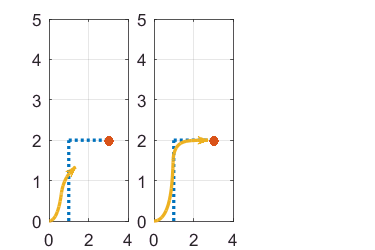

clear all;clf
LW = 'linewidth';
MS = 'markersize';
a = chebfun({@(t) 1+1i*t,@(t) -1+2i+t}, [0  2 4]);
N = chebop(0,4);
N.lbc = 0;
CC = [0.5 1];
for j = 1:2
    C=CC(j);
    N.op=@(t,z) diff(z) - C*(a(t) -z)/abs((a(t)-z));
    subplot(1,3,j),plot(a,':',LW,2); hold on; grid on
    axis([0 4 0 5])
    plot(a(end),'.',LW,2,MS,20);
    z = N\0;
    arrowplot(z,LW,2)
end

 Here if the antelope is manuavering, the time for the lioness to catch it is longer(really?). In the natural sicence TV show, you may see antelopes have their own statedgy to escape lions attack, manuervering!

 This pursuit evasion alogorithm, keep the steering command to follow the line of sight,was polpular in the early stage of World War II for anti-aircraft missiles. However ther are another alogothms to keep the rate of line of sight, called Proportional Navigation Algorithm.The last one is needed smaller steering commands than that of the first.